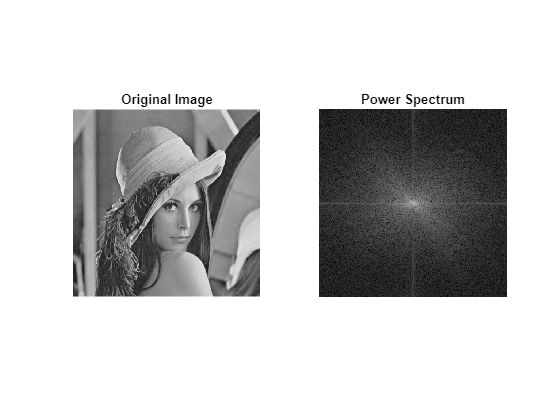

close all; clear; clc;
[f, map] = imread('lena.bmp');
[height, width] = size(f);
f = im2double(f); F = fftshift(fft2(f));
figure();
subplot(1,2,1); imshow(f); title('Original Image');
subplot(1,2,2); imshow(mat2gray(log(1+abs(F)))); title('Power Spectrum');

% Kernel of Horizontal Motion Blur
d = 40;
h = CreateHorizontalMotionBlurredKernel(d)

h =     0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123    0.0123


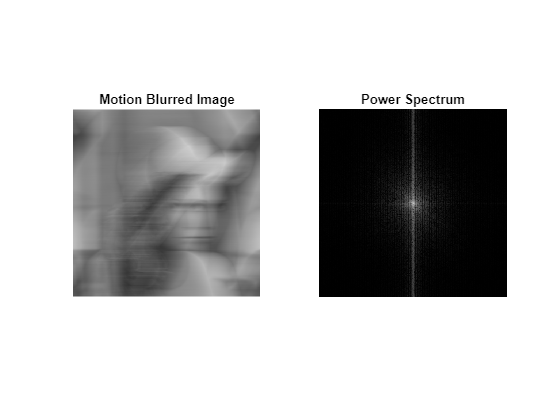

% Horizontal Motion Blur on Lena image with d=40
g = MotionBlurInFrequencyDomain(f, h);

figure();
subplot(1,2,1); imshow(g); title('Motion Blurred Image');
subplot(1,2,2); imshow(mat2gray(log(1+abs(fftshift(fft2(g)))))); title('Power Spectrum');

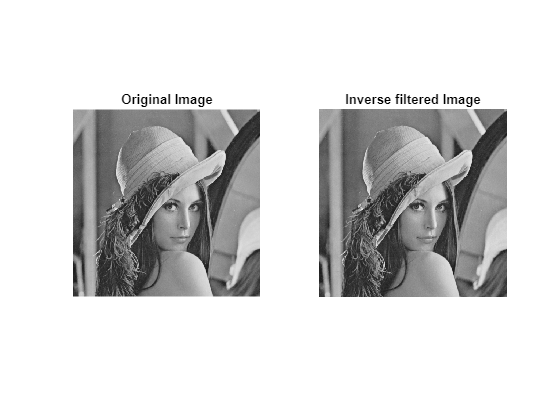

% Just Motion Blur, so InverseFilter is OK
g_hat = InverseFilterInFrequencyDomain(g, h, 0.001);

figure();
subplot(1,2,1); imshow(f); title('Original Image');
subplot(1,2,2); imshow(g_hat); title('Inverse filtered Image')

% Add a gaussian noise, so InverseFilter will fail.
var = 0.05;
n = imnoise(zeros(height,width), 'gaussian', var);
g = MotionBlurInFrequencyDomain(f, h) + n;
% So we need to use WienerFilter

% use SNR to find K
K = 1/ComputeSpectrumSNR(f, n)

K = 0.0384

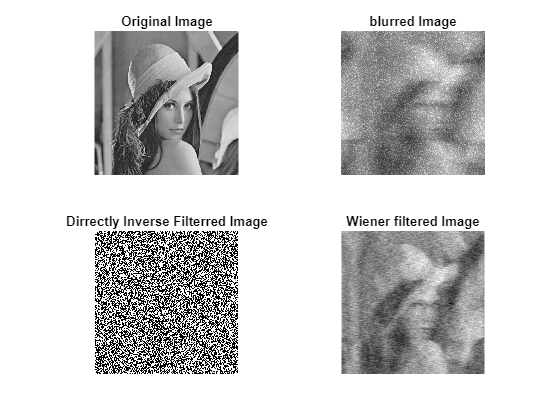

f_hat = MyWienerFilter(g, h, K, 0.001);

figure();
subplot(2,2,1); imshow(f); title('Original Image');
subplot(2,2,2); imshow(g); title('blurred Image');
subplot(2,2,3); imshow(InverseFilterInFrequencyDomain(g, h, 0.001)); title('Dirrectly Inverse Filterred Image');
subplot(2,2,4); imshow(f_hat); title('Wiener filtered Image')

### **Compare with different K**

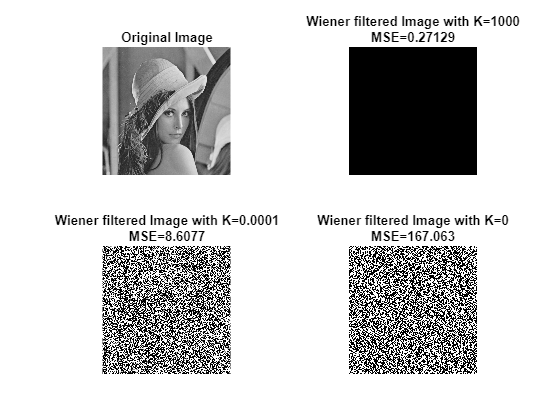

K = [1000, 0.0001, 0]; % pick 3 values of K yourself

figure();
subplot(2,2,1); imshow(f); title('Original Image');
for i = 1:3
    f_hat = MyWienerFilter(g, h, K(i), 0.001);
    mse = sum((f - f_hat).^2, 'all') / numel(f);
    subplot(2,2,i+1); imshow(f_hat); 
    title({['Wiener filtered Image with K=' num2str(K(i)) ];['MSE=' num2str(mse)]}) % implematation here for K and MSE
    
end

### **Question 1**

function h = CreateHorizontalMotionBlurredKernel(d)
% h = CreateHorizontalMotionBlurredKernel(d)
% for example, if d=1, h=[1/3, 1/3, 1/3]; if d=3, h=[1/7,1/7,1/7,1/7,1/7,1/7,1/7]
    % implematation here
   
    % Calculate the size of the kernel
    kernelSize = 2 * d + 1;

    % Create the kernel using an averaging filter
    h = ones(1, kernelSize) / kernelSize; 
end


### **Question 2**

function g = MotionBlurInFrequencyDomain(f, h)
% g = MotionBlurInFrequencyDomain(f, h)
% 'f' is the original image, 'h' is the kernel of motion blur
% All inputs and output are in the spatial domain but your process is in the frequency domain

    % Take the 2D Fourier Transforms of the image and kernel
    F = fftshift(fft2(f));
    H = fftshift(fft2(h, size(f, 1), size(f, 2)));
    
    % Perform element-wise multiplication in the frequency domain
    G = F .* H;
    
    % Take the inverse Fourier Transform to get the degraded image
    g = ifft2(ifftshift(G));
    
    % Ensure the output is real (due to potential numerical errors)
    g = real(g);
end

### **Question 3**

function f_hat = InverseFilterInFrequencyDomain(g, h, epsilon)
% f_hat = InverseFilterInFrequencyDomain(g, h, epsilon)
% 'g' is degraded image, 'h' is kernel of motion blur
% All inputs and output is in spatial domain but your process has to be in frequency domain 

    % Take the 2D Fourier Transforms of the degraded image and kernel
    G = fftshift(fft2(g));
    H = fftshift(fft2(h, size(g, 1), size(g, 2)));

    % Compute the regularization term
    R = ones(size(H));
    R(abs(H) > epsilon) = 1 ./ H(abs(H) > epsilon);

    % Compute the inverse filter in the frequency domain with regularization
    F_hat = R .* G;

    % Take the inverse Fourier Transform to get the estimated image
    f_hat = ifft2(ifftshift(F_hat));

    % Ensure the output is real (due to potential numerical errors)
    f_hat = real(f_hat);

end

### **Question 4**

function snr = ComputeSpectrumSNR(f, n)
% abs(N(u,v)).^2 / abs(N(u,v)).^2

    % please copy from PDF file
    F = fftshift(fft2(f)); 
    N = fftshift(fft2(n)); 
    S_n = sum((abs(N).^2), 'all'); 
    S_f = sum((abs(F).^2), 'all'); 
    snr = S_f./S_n;

end

function f_hat = MyWienerFilter(g, h, K, epsilon)
% f_hat = MyWiennerFilter(g, f, h, n, epsilon)
% 'g' is degraded image, 'f' is original image, 'h' is kernel of motion
% blur, 'n' is noise, epsilon is for R(u,v)
% All inputs and output is in spatial domain but your process has to be in frequency domain 
    
    % Take the 2D Fourier Transforms of the degraded image and kernel
    G = fftshift(fft2(g));
    H = fftshift(fft2(h, size(g, 1), size(g, 2)));

    % Calculate the Wiener filter in the frequency domain
    R = ones(size(H));
    R(abs(H) > epsilon) = 1 ./ H(abs(H) > epsilon);

    F_hat = R .* abs(H).^2 ./ (abs(H).^2 + K) .* G;

    % Take the inverse Fourier Transform to get the estimated image
    f_hat = ifft2(ifftshift(F_hat));

    % Ensure the output is real (due to potential numerical errors)
    f_hat = real(f_hat);

end
